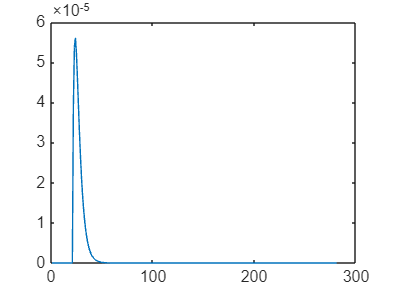


%% intro
clearvars; close all; clc;
%rng("shuffle")
%rng(2,"twister")
rng(2025,'twister'); 

run("main_channel.m")

newresponse = zeros(1,800);
newresponse(1:281) = Final_response(1:281);
newresponse(300:451) = Final_response(94:245)*0.3;
newresponse(600:751) = Final_response(94:245)*0.6;

H = Final_response;
%H = newresponse;
%H = [1, 0, 0, 0, 0];

figure
plot(H)

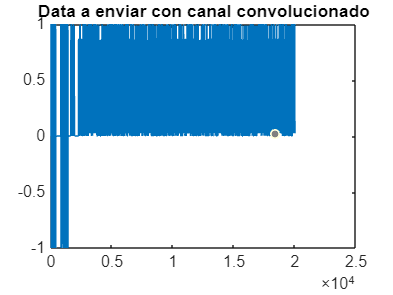




%% 1) Define Channel Emulation
% The channel H is your "Final_response"
% For example, 
H = Final_response;

%% 2) OOK Passband Preamble Generation
Fs = 2e6;              % Sample rate (Hz)
Rb = 1e3;              % Bitrate (bits/s)
Fc = 1e5;              % Carrier (Hz)
samplesPreamb = 100;   % Samples per preamble bit (Fs/Rb = 2000 if Rb=1e3 and Fs=2e6,
                       % but here it's set to 100 as in your example)

preambleBits = [1,1,1,1, 0,0,0,0, 1,0,1,0, 1,1,0,0]; 
% 16 bits => repeated 100 times => 1600 samples

% Create OOK baseband for preamble
preambleBase = repelem(preambleBits, samplesPreamb);  % length = 16*100 = 1600

% Modulate onto carrier
t = (0 : length(preambleBase)-1) / Fs;
carrier = cos(2*pi*Fc*t);
passbandPreamble = preambleBase .* carrier;

%% 3) OOK Pilot + Data (Baseband) with RRC, then convolve with H
samplesPerSym = 10;
rolloff       = 0.25;
span          = 6;
rcFilter      = rcosdesign(rolloff, span, samplesPerSym, 'sqrt');
filtDelay     = (length(rcFilter)-1)/2;


% Pilot
pilotLen   = 32;                        % 32 bits
pilotBits  = randi([0,1], pilotLen, 1); % or a fixed pattern if you prefer
pilotSyms  = 2*pilotBits - 0;           % BPSK mapping: 0->-1, 1->+1

% Data
numDataBits = 24717; 
dataBits    = randi([0,1], numDataBits,1);
dataSyms    = 2*dataBits - 0;           % BPSK mapping: 0->-1, 1->+1


% Upsample
pilotUp = upsample(pilotSyms, samplesPerSym);
dataUp  = upsample(dataSyms, samplesPerSym);

% RRC pulse shaping
pilotRRC = conv(pilotUp, rcFilter, 'full');
dataRRC  = conv(dataUp, rcFilter, 'full');

% Optional: remove the filter tails at Tx if desired
pilotRRC = pilotRRC(filtDelay+1 : end-filtDelay);
dataRRC  = dataRRC(filtDelay+1 : end-filtDelay);

% Convolve with channel H
pilotConv = conv(pilotUp, H, 'full');
dataConv  = conv(dataUp,  H, 'full');

%% 4) Combine Everything into One Packet
txPacket = [ ...
    passbandPreamble,       ... % (1600 samples, passband)
    pilotConv.'/max(pilotConv),   ... % (baseband, OOK+RRC+H)
    dataConv.'/max(dataConv)      ... % (baseband, OOK+RRC+H)
];

% (Row vector for convenience)
txPacket = txPacket(:).';

%% 5) Save to File (Optional)
% write_float_binary is your custom function; or use fwrite, etc.
write_float_binary(txPacket, 'envioOOKyDATA.bin');
read = read_float_binary('envioOOKyDATA.bin')';
figure
plot(read(1:20001))
title("Data a enviar con canal convolucionado")

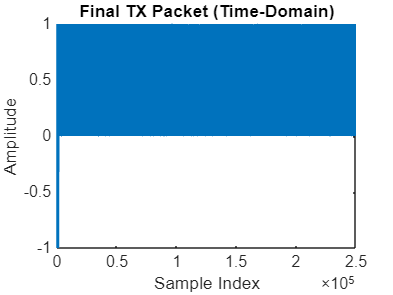



%% 6) Plot
figure;
plot(txPacket);
title('Final TX Packet (Time-Domain)');
xlabel('Sample Index');
ylabel('Amplitude');

function v = write_float_binary (data, filename)

  %% usage: write_float_binary (data, filename)
  %%
  %%  open filename and write data to it as 32 bit floats
  %%

  m = nargchk (1,2,nargin);
  if (m)
    usage (m);
  end

  f = fopen (filename, 'wb');
  if (f < 0)
    v = 0;
  else
    v = fwrite (f, data, 'float');
    fclose (f);
  end
end


function v = read_float_binary (filename, count)

  %% usage: read_float_binary (filename, [count])
  %%
  %%  open filename and return the contents, treating them as
  %%  32 bit floats
  %%

  m = nargchk (1,2,nargin);
  if (m)
    usage (m);
  end

  if (nargin < 2)
    count = Inf;
  end

  f = fopen (filename, 'rb');
  if (f < 0)
    v = 0;
  else
    v = fread (f, count, 'float');
    fclose (f);
  end
end

